# **Analyzing Neural Time Series Data**

*Theory and Practice: Mike X Cohen*

*Presented by: Armin Toghi*

*IDS Executive Member of Signal and Neuroimaging Department*

[armintoghi85@gmail.com](http://armintoghi85@gmail.com)

### Connectivity Methods:

### Power-based Connectivity

#### **Spearman versus Pearson Coefficient for Power Correlations**  

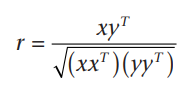

The superscript T indicates the matrix transpose. This formulation assumes that the data are electrodes-by-time;  Interpreting the Pearson correlation coefficient relies on the assumption that the data are normally distributed. Violations of this assumption will introduce a bias into the correlation coefficient  

The Spearman correlation (also sometimes called Spearman *ρ*) is similar to the Pearson correlation, but it is nonparametric. Conceptually, however, it is important to understand that the only difference between the Spearman and the Pearson correlation is that the Spearman correlation involves rank-transforming the data before applying equation in the top. There are two reasons why within-subject power correlations should be done with the Spearman and not the Pearson correlation: power data are nonnormally distributed, and they contain outliers.  

anscombe = [
  % series 1    series 2    series 3     series 4
    10  8.04    10  9.14    10  7.46     8  6.58;
     8  6.95     8  8.14     8  6.77     8  5.76;
    13  7.58    13  8.76    13 12.74     8  7.71;
     9  8.81     9  8.77     9  7.11     8  8.84;
    11  8.33    11  9.26    11  7.81     8  8.47;
    14  9.96    14  8.10    14  8.84     8  7.04;
     6  7.24     6  6.13     6  6.08     8  5.25;
     4  4.26     4  3.10     4  5.39     8  5.56;
    12 10.84    12  9.13    12  8.15     8  7.91;
     7  4.82     7  7.26     7  6.42     8  6.89;
     5  5.68     5  4.74     5  5.73    19 12.50;
    ];


% plot and compute correlations
figure
for i=1:4
    subplot(2,2,i)
    plot(anscombe(:,(i-1)*2+1),anscombe(:,(i-1)*2+2),'.')
    lsline
    corr_p = corr(anscombe(:,(i-1)*2+1),anscombe(:,(i-1)*2+2),'type','p');
    corr_s = corr(anscombe(:,(i-1)*2+1),anscombe(:,(i-1)*2+2),'type','s');
    title([ 'r_p=' num2str(round(corr_p*1000)/1000) '; r_s=' num2str(round(corr_s*1000)/1000) ])
end

Anscombe’s quartet is a set of four pairs of vectors that have the same basic statistical properties and Pearson correlation coefficients but, as you can see in figure 27.1, very  different distributions.  

Correlation coefficients (whether computed by the Spearman or the Pearson method) are not drawn from a normal distribution; they have a bounded distribution between –1 and +1. Although in practice the observed correlation coefficients might appear normally distributed, they should be transformed before statistical evaluation. The most typical transform for correlation coefficients is the Fisher-*Z *transform, which effectively “stretches out” the numbers so that they have a broader and more normal-looking distribution.

#### Power correlation over time

The power time series from the two electrodes can be in the same frequency band or in different frequency bands. If they are in different frequency bands, the correlation would reflect cross-frequency coupling (chapter 30) (Bruns et al. 2000; Hipp et al. 2012). 

load sampleEEGdata.mat
sensor1 = 'fz';
sensor2 = 'p5';

centerfreq = 6; % in Hz
trial2plot = 10;

% setup wavelet convolution and outputs
time = -1:1/EEG.srate:1;
half_of_wavelet_size = (length(time)-1)/2;

% FFT parameters
n_wavelet     = length(time);
n_data        = EEG.pnts*EEG.trials;
n_convolution = n_wavelet+n_data-1;
wavelet_cycles= 4.5;

times2plot = dsearchn(EEG.times',[-300 1200]');


fft_data1 = fft(reshape(EEG.data(strcmpi(sensor1,{EEG.chanlocs.labels}),:,:),1,EEG.pnts*EEG.trials),n_convolution);
fft_data2 = fft(reshape(EEG.data(strcmpi(sensor2,{EEG.chanlocs.labels}),:,:),1,EEG.pnts*EEG.trials),n_convolution);

% create wavelet and run convolution
fft_wavelet             = fft(exp(2*1i*pi*centerfreq.*time) .* exp(-time.^2./(2*( wavelet_cycles /(2*pi*centerfreq))^2)),n_convolution);
convolution_result_fft  = ifft(fft_wavelet.*fft_data1,n_convolution) * sqrt(wavelet_cycles /(2*pi*centerfreq));
convolution_result_fft  = convolution_result_fft(half_of_wavelet_size+1:end-half_of_wavelet_size);
convolution_result_fft1 = reshape(convolution_result_fft,EEG.pnts,EEG.trials);

fft_wavelet             = fft(exp(2*1i*pi*centerfreq.*time) .* exp(-time.^2./(2*( wavelet_cycles /(2*pi*centerfreq))^2)),n_convolution);
convolution_result_fft  = ifft(fft_wavelet.*fft_data2,n_convolution) * sqrt(wavelet_cycles /(2*pi*centerfreq));
convolution_result_fft  = convolution_result_fft(half_of_wavelet_size+1:end-half_of_wavelet_size);
convolution_result_fft2 = reshape(convolution_result_fft,EEG.pnts,EEG.trials);

% keep only requested time regions
convolution_result_fft1 = convolution_result_fft1(times2plot(1):times2plot(2),:);
convolution_result_fft2 = convolution_result_fft2(times2plot(1):times2plot(2),:);

figure
subplot(211)
plot(EEG.times(times2plot(1):times2plot(2)),abs(convolution_result_fft1(:,trial2plot)).^2)
hold on
plot(EEG.times(times2plot(1):times2plot(2)),abs(convolution_result_fft2(:,trial2plot)).^2,'r')
xlabel('Time (ms)')
set(gca,'xlim',EEG.times(times2plot))
legend({sensor1;sensor2})

subplot(223)
plot(abs(convolution_result_fft1(:,trial2plot)).^2,abs(convolution_result_fft2(:,trial2plot)).^2,'.')
title('Power relationship')
xlabel([ sensor1 ' ' num2str(centerfreq) 'Hz power' ])
ylabel([ sensor2 ' ' num2str(centerfreq) 'Hz power' ])
r=corr(abs(convolution_result_fft1(:,trial2plot)).^2,abs(convolution_result_fft2(:,trial2plot)).^2,'type','p');
legend([ 'Pearson R = ' num2str(r) ]);

subplot(224)
plot(tiedrank(abs(convolution_result_fft1(:,trial2plot)).^2),tiedrank(abs(convolution_result_fft2(:,trial2plot)).^2),'.')
title('Rank-power relationship')
xlabel([ sensor1 ' ' num2str(centerfreq) 'Hz rank-power' ])
ylabel([ sensor2 ' ' num2str(centerfreq) 'Hz rank-power' ])
r=corr(abs(convolution_result_fft1(:,trial2plot)).^2,abs(convolution_result_fft2(:,trial2plot)).^2,'type','s');
legend([ 'Spearman Rho = ' num2str(r) ]);
set(gca,'ylim',get(gca,'xlim'))

 Power correlations over time are not limited to instantaneous correlations as was illustrated in figure 27.4 . You can perform a **cross-correlation analysis**, which will reveal whether peak connectivity is observed when one time series is temporally shifted relative to the other.  

% Compute how many time points are in one cycle, and limit xcov to this lag
nlags = round(EEG.srate/centerfreq);

% note that data are first tiedrank'ed, which results in a Spearman rho
% instead of a Pearson r. 
[corrvals,corrlags] = xcov(tiedrank(abs(convolution_result_fft1(:,trial2plot)).^2),tiedrank(abs(convolution_result_fft2(:,trial2plot)).^2),nlags,'coeff');

% convert correlation lags from indices to time in ms
corrlags = corrlags * 1000/EEG.srate; 

figure
plot(corrlags,corrvals,'-o','markerface','w')
hold on
plot([0 0],get(gca,'ylim'))
xlabel([ sensor1 ' leads --- Time lag in ms --- ' sensor2 ' leads' ])
ylabel('Correlation coefficient')

#### Power correlation over trial

select time-frequency windows for two electrodes (the time-frequency windows need not be the same for both electrodes), extract power from that window from each trial (averaging over all time-frequency points within that window), and compute one correlation coefficient.

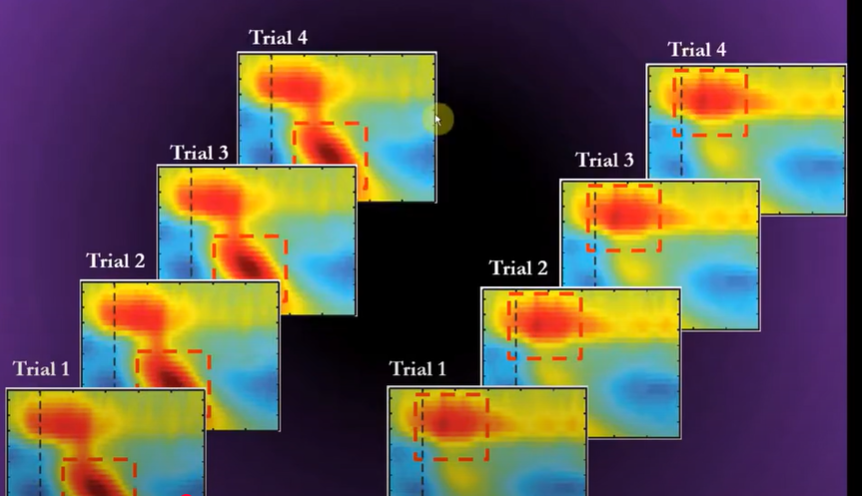

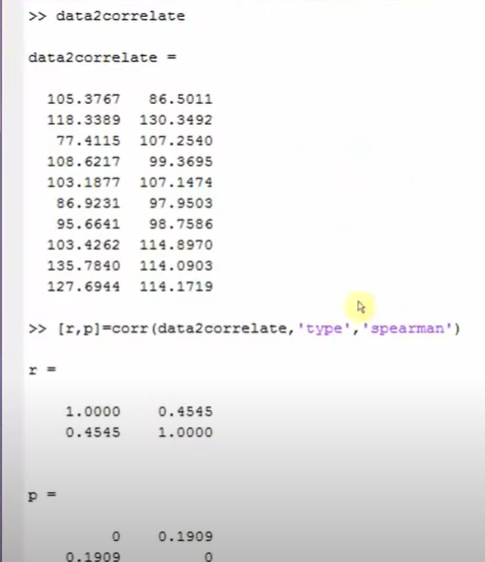

sensor1 = 'poz';
sensor2 = 'fz';

timewin1 = [ -300 -100 ]; % in ms relative to stim onset
timewin2 = [  200  400 ];

centerfreq1 =  6; % in Hz
centerfreq2 =  6;


% convert time from ms to index
timeidx1 = zeros(size(timewin1));
timeidx2 = zeros(size(timewin2));
for i=1:2
    [junk,timeidx1(i)] = min(abs(EEG.times-timewin1(i)));
    [junk,timeidx2(i)] = min(abs(EEG.times-timewin2(i)));
end

% setup wavelet convolution and outputs
time = -1:1/EEG.srate:1;
half_of_wavelet_size = (length(time)-1)/2;

% FFT parameters
n_wavelet     = length(time);
n_data        = EEG.pnts*EEG.trials;
n_convolution = n_wavelet+n_data-1;
wavelet_cycles= 4.5;

% FFT of data (note: this doesn't change on frequency iteration)
fft_data1 = fft(reshape(EEG.data(strcmpi(sensor1,{EEG.chanlocs.labels}),:,:),1,EEG.pnts*EEG.trials),n_convolution);
fft_data2 = fft(reshape(EEG.data(strcmpi(sensor2,{EEG.chanlocs.labels}),:,:),1,EEG.pnts*EEG.trials),n_convolution);

% initialize output time-frequency data
corrdata = zeros(EEG.trials,2);

% create wavelet and run convolution
fft_wavelet            = fft(exp(2*1i*pi*centerfreq1.*time) .* exp(-time.^2./(2*( wavelet_cycles /(2*pi*centerfreq1))^2)),n_convolution);
convolution_result_fft = ifft(fft_wavelet.*fft_data1,n_convolution) * sqrt(wavelet_cycles /(2*pi*centerfreq1));
convolution_result_fft = convolution_result_fft(half_of_wavelet_size+1:end-half_of_wavelet_size);
convolution_result_fft = reshape(convolution_result_fft,EEG.pnts,EEG.trials);
analyticsignal1        = abs(convolution_result_fft).^2;

fft_wavelet            = fft(exp(2*1i*pi*centerfreq2.*time) .* exp(-time.^2./(2*( wavelet_cycles /(2*pi*centerfreq2))^2)),n_convolution);
convolution_result_fft = ifft(fft_wavelet.*fft_data2,n_convolution) * sqrt(wavelet_cycles /(2*pi*centerfreq2));
convolution_result_fft = convolution_result_fft(half_of_wavelet_size+1:end-half_of_wavelet_size);
convolution_result_fft = reshape(convolution_result_fft,EEG.pnts,EEG.trials);
analyticsignal2        = abs(convolution_result_fft).^2;


% Panel A: correlation in a specified window
tfwindowdata1 = mean(analyticsignal1(timeidx1(1):timeidx1(2),:),1);
tfwindowdata2 = mean(analyticsignal2(timeidx2(1):timeidx2(2),:),1);
figure
subplot(121)
plot(tfwindowdata1,tfwindowdata2,'.')
axis square
title([ 'TF window correlation, r_p=' num2str(corr(tfwindowdata1',tfwindowdata2','type','p')) ])
xlabel([ sensor1 ': ' num2str(timewin1(1)) '-' num2str(timewin1(2)) '; ' num2str(centerfreq1) ' Hz' ])
ylabel([ sensor2 ': ' num2str(timewin2(1)) '-' num2str(timewin2(2)) '; ' num2str(centerfreq2) ' Hz' ])


% also plot rank-transformed data
subplot(122)
plot(tiedrank(tfwindowdata1),tiedrank(tfwindowdata2),'.')
axis square
xlabel([ sensor1 ': ' num2str(timewin1(1)) '-' num2str(timewin1(2)) '; ' num2str(centerfreq1) ' Hz' ])
ylabel([ sensor2 ': ' num2str(timewin2(1)) '-' num2str(timewin2(2)) '; ' num2str(centerfreq2) ' Hz' ])
title([ 'TF window correlation, r_p=' num2str(corr(tfwindowdata1',tfwindowdata2','type','s')) ])


% panel B: correlation over time
corr_ts = zeros(size(EEG.times));
for ti=1:EEG.pnts
    corr_ts(ti) = corr(analyticsignal1(ti,:)',analyticsignal2(ti,:)','type','s');
end

figure
plot(EEG.times,corr_ts)
set(gca,'xlim',[-200 1200])
xlabel('Time (ms)'), ylabel('Spearman''s rho')



% Panel C: exploratory time-frequency power correlations
times2save = -200:25:1200;
frex = logspace(log10(2),log10(40),20);


times2save_idx = zeros(size(times2save));
for i=1:length(times2save)
    [junk,times2save_idx(i)] = min(abs(EEG.times-times2save(i)));
end

% rank-transforming the data can happen outside the frequency loop
seeddata_rank = tiedrank(tfwindowdata2);

% initialize output correlation matrix
expl_corrs = zeros(length(frex),length(times2save));

for fi=1:length(frex)
    
    % get power (via wavelet convolution) from signal1
    fft_wavelet            = fft(exp(2*1i*pi*frex(fi).*time) .* exp(-time.^2./(2*( wavelet_cycles /(2*pi*frex(fi)))^2)),n_convolution);
    convolution_result_fft = ifft(fft_wavelet.*fft_data1,n_convolution) * sqrt(wavelet_cycles /(2*pi*frex(fi)));
    convolution_result_fft = convolution_result_fft(half_of_wavelet_size+1:end-half_of_wavelet_size);
    convolution_result_fft = reshape(convolution_result_fft,EEG.pnts,EEG.trials);
    analyticsignal1        = abs(convolution_result_fft).^2;
    
    for ti=1:length(times2save)
        expl_corrs(fi,ti) = 1-6*sum((seeddata_rank-tiedrank(analyticsignal1(times2save_idx(ti),:))).^2)/(EEG.trials*(EEG.trials^2-1));
    end
end

figure
contourf(times2save,frex,expl_corrs,40,'linecolor','none')
set(gca,'clim',[-.4 .4],'yscale','log','ytick',round(logspace(log10(frex(1)),log10(frex(end)),8)))
xlabel('Time (ms)'), ylabel('Frequency (Hz)')
title([ 'Correlation over trials from seed ' sensor2 ', ' num2str(centerfreq2) ' Hz and ' num2str(timewin2(1)) '-' num2str(timewin2(2)) ' ms' ])
colorbar

#### Partial correlation

Partial correlations allow you to measure the linear or monotonic (via Pearson or Spearman correlation) relationship between two variables *(X and Y) while holding constant a third variable (Z).* In the case of EEG power-based connectivity, partial correlations can be useful for two reasons. First, they can be used to test hypotheses about networks comprising more than two nodes. Second, partial correlations can be used to minimize volume conduction artifacts during power correlations. Consider that X and Y are two electrodes spaced many centimeters apart from each other, and that X and Z are physically neighboring electrodes. If the power correlation between X and Y is very similar to the correlation between Z and Y, this could be attributed to volume conduction between X and Z. **Thus, computing the partial correlation between X and Y, holding Z constant, will remove shared variance between X and Z, much of which reflects volume conduction.**

seed_chan     = 'fz';
target_chan   = 'f6';
control_chan  = 'f1';

clim = [0 .6];

% wavelet parameters
min_freq = 2;
max_freq = 40;
num_frex = 15;

% downsampled times
times2save = -200:50:800;
% times2save = EEG.times; % uncomment this line for figure 27.8


% other wavelet parameters
frequencies = logspace(log10(min_freq),log10(max_freq),num_frex);
time = -1:1/EEG.srate:1;
half_of_wavelet_size = (length(time)-1)/2;

% FFT parameters
n_wavelet     = length(time);
n_data        = EEG.pnts*EEG.trials;
n_convolution = n_wavelet+n_data-1;
wavelet_cycles= 4.5;

times2saveidx = dsearchn(EEG.times',times2save');

% FFT of data (note: this doesn't change on frequency iteration)
fft_data_seed = fft(reshape(EEG.data(strcmpi(seed_chan,{EEG.chanlocs.labels}),:,:),1,EEG.pnts*EEG.trials),n_convolution);
fft_data_trgt = fft(reshape(EEG.data(strcmpi(target_chan,{EEG.chanlocs.labels}),:,:),1,EEG.pnts*EEG.trials),n_convolution);
fft_data_ctrl = fft(reshape(EEG.data(strcmpi(control_chan,{EEG.chanlocs.labels}),:,:),1,EEG.pnts*EEG.trials),n_convolution);


% initialize output time-frequency data
tf_corrdata = zeros(length(frequencies),length(times2save),2);

for fi=1:length(frequencies)
    
    % create wavelet and get its FFT
    fft_wavelet = fft(exp(2*1i*pi*frequencies(fi).*time) .* exp(-time.^2./(2*( wavelet_cycles /(2*pi*frequencies(fi)))^2))/frequencies(fi),n_convolution);
    
    
    % convolution for all three sites (save only power)
    convolution_result_fft = ifft(fft_wavelet.*fft_data_seed,n_convolution) * sqrt(wavelet_cycles /(2*pi*frequencies(fi)));
    convolution_result_fft = convolution_result_fft(half_of_wavelet_size+1:end-half_of_wavelet_size);
    conv_result_seed = abs(reshape(convolution_result_fft,EEG.pnts,EEG.trials)).^2;
    
    convolution_result_fft = ifft(fft_wavelet.*fft_data_trgt,n_convolution) * sqrt(wavelet_cycles /(2*pi*frequencies(fi)));
    convolution_result_fft = convolution_result_fft(half_of_wavelet_size+1:end-half_of_wavelet_size);
    conv_result_trgt = abs(reshape(convolution_result_fft,EEG.pnts,EEG.trials)).^2;
    
    convolution_result_fft = ifft(fft_wavelet.*fft_data_ctrl,n_convolution) * sqrt(wavelet_cycles /(2*pi*frequencies(fi)));
    convolution_result_fft = convolution_result_fft(half_of_wavelet_size+1:end-half_of_wavelet_size);
    conv_result_ctrl = abs(reshape(convolution_result_fft,EEG.pnts,EEG.trials)).^2;
    
    % downsample and rank transform all data
    conv_result_seed = tiedrank(conv_result_seed(times2saveidx,:)')';
    conv_result_trgt = tiedrank(conv_result_trgt(times2saveidx,:)')';
    conv_result_ctrl = tiedrank(conv_result_ctrl(times2saveidx,:)')';
    
    for ti=1:length(times2save)
        
        % compute bivariate correlations
        r_st = 1-6*sum((conv_result_seed(ti,:)-conv_result_trgt(ti,:)).^2)/(EEG.trials*(EEG.trials^2-1));
        r_sc = 1-6*sum((conv_result_seed(ti,:)-conv_result_ctrl(ti,:)).^2)/(EEG.trials*(EEG.trials^2-1));
        r_tc = 1-6*sum((conv_result_ctrl(ti,:)-conv_result_trgt(ti,:)).^2)/(EEG.trials*(EEG.trials^2-1));
        
        % bivariate correlation for comparison
        tf_corrdata(fi,ti,1) = r_st;

        % compute partial correlation and store in results matrix
        tf_corrdata(fi,ti,2) = (r_st-r_sc*r_tc) / ( sqrt(1-r_sc^2)*sqrt(1-r_tc^2) );
    end
end

% plot
figure
for i=1:2
    subplot(1,2,i)
    contourf(times2save,frequencies,squeeze(tf_corrdata(:,:,i)),40,'linecolor','none')
    set(gca,'clim',clim,'xlim',[-200 800],'yscale','log','ytick',logspace(log10(frequencies(1)),log10(frequencies(end)),6),'yticklabel',round(logspace(log10(frequencies(1)),log10(frequencies(end)),6)*10)/10)
    axis square
    if i==1
        title([ 'Correlation between ' seed_chan ' and ' target_chan ])
    else
        title([ 'Partial correlation between ' seed_chan ' and ' target_chan ])
    end
    xlabel('Time (ms)'), ylabel('Frequency (Hz)')
end

#### **Describing This Analysis in Your Methods Section**

Similar to phase-based connectivity methods, there are many possibilities for power-based measures of connectivity. Provide a justification for why you applied one method for computing power-based connectivity over other methods and include a clear description of the analysis performed. Describe the method clearly and state the frequencies, time segment lengths, and other relevant parameters. State whether you used Pearson or Spearman correlation, and, if you used Pearson correlation, provide a justification for not using the Spearman rank correlation.  

**Exercise:**

1. Perform a power correlation analysis over time. Pick two electrodes and use a sliding time segment of three cycles (1.5 cycles on either side of each center time point). Average the results over trials. Perform this analysis at three frequencies and plot the time series of correlation coefficients. Next, repeat the analysis twice, using fixed time-segment lengths of 150 ms and 900 ms. Do the results differ according to the time segment length and the frequency band, and how are they different? In what situations would it be beneficial to use each window width parameter, and in what situations might problems or limitations arise? 

2. Select two “ seed ” time-frequency-electrode windows and perform an exploratory power correlation over trials at one selected “ target ” electrode, as in figure 27.6C (plate 19). Show the results in separate plots, and then show a time-frequency plot of correlation coefficient differences between the two seeds (Fisher-*Z *transform the coefficients before subtraction). Are there any striking qualitative differences between the two plots, and did plotting the difference map make the differences easier or more difficult to interpret?  